#  KUKA-KR10-R1100-2 Robotic arm

Github Link : [https://github.com/mostafa-metwaly/DoNRs-HW3](https://github.com/mostafa-metwaly/DoNRs-HW3)

Mostafa Osama 

Innopolis University

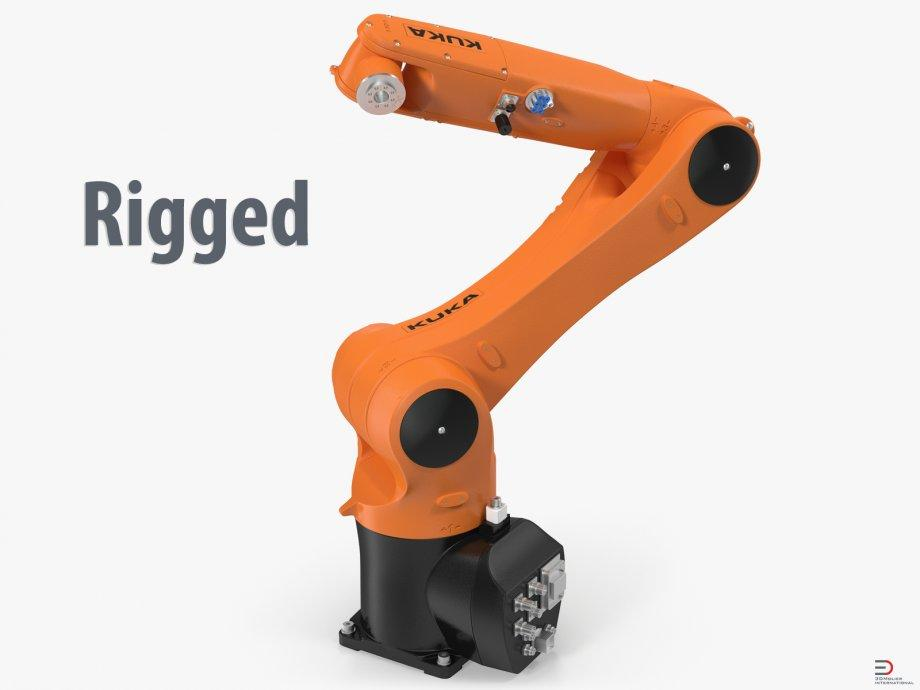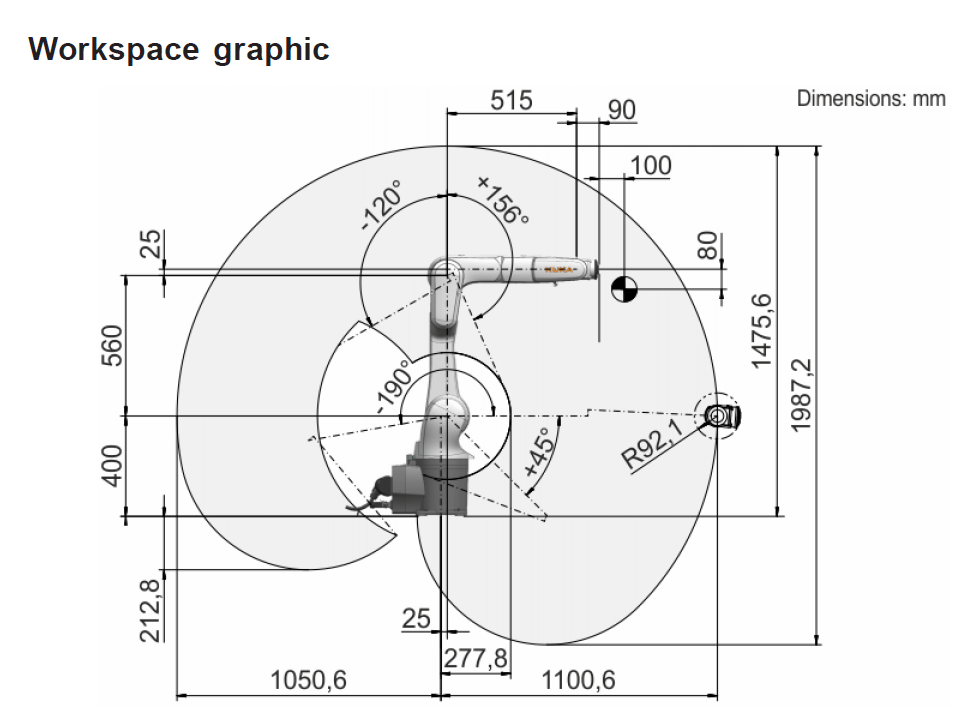

clear all
close all
clc
% set angles as symbolical
syms q q1 q2 q3 q4 q5 q6 real
%Link lengths
d1=400;d2=25;d3=560;d4=25;d5=515;d6=90;
d=[d1, d2, d3, d4, d5, d6];
q=[q1 q2 q3 q4 q5 q6];

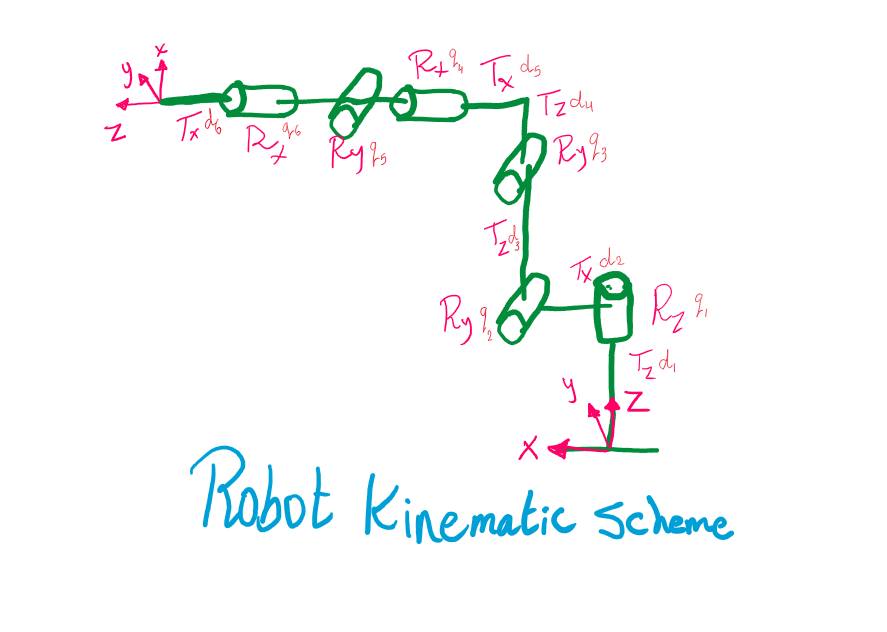

## Forward Kinematics


$$H={T_z \left(\textrm{d1}\right)\;\ldotp \;R}_z \left(\textrm{q1}\right)\cdot T_x \left(\textrm{d2}\right)\cdot R_y \left(\textrm{q2}\right)\cdot T_z \left(\textrm{d3}\right)\cdot R_y \left(\textrm{q3}\right)\cdot T_z \left(\textrm{d4}\right)\;\cdot {\;T}_x \left(\textrm{d5}\right)\;\ldotp \;R_x \left(\textrm{q4}\right)\cdot R_y \left(\textrm{q5}\right)\;{\cdot \;R}_x \left(\textrm{q6}\right)\cdot T_x \left(\textrm{d6}\right)$$


% FK symbolical
FK=simplify(Tz(d1)*Rz(q(1))*Tx(d2)*Ry(q(2))*Tz(d3)*Ry(q(3))*Tz(d4)*Tx(d5)*Rx(q(4))*Ry(q(5))*Rx(q(6))*Tx(d6))


disp('All 0 configuration')

All 0 configuration


q_test = [0 0 0 0 0 0] % all 0 configuration

q_test =      0     0     0     0     0     0


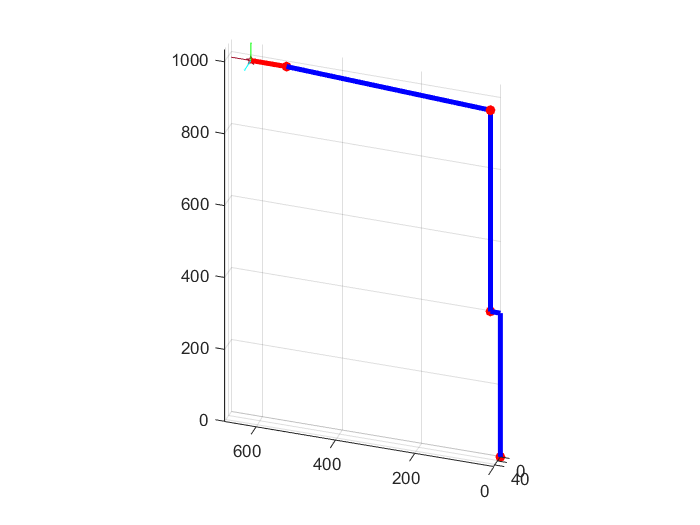

draw_robot(q_test,d)

view([198.474 30.562])

% Substitute angles in symbolical form and convert to double
double(subs(FK, [q1 q2 q3 q4 q5 q6], q_test))

ans =      1     0     0   630
     0     1     0     0
     0     0     1   985
     0     0     0     1



disp('Random configuration')

Random configuration



q1v=160*pi/180;
q2v=40*pi/180;
q3v=-60*pi/180;
q4v=-130*pi/180;
q5v=70*pi/180;
q6v=-30*pi/180;
q_test=[q1v q2v q3v q4v q5v q6v]

q_test =     2.7925    0.6981   -1.0472   -2.2689    1.2217   -0.5236


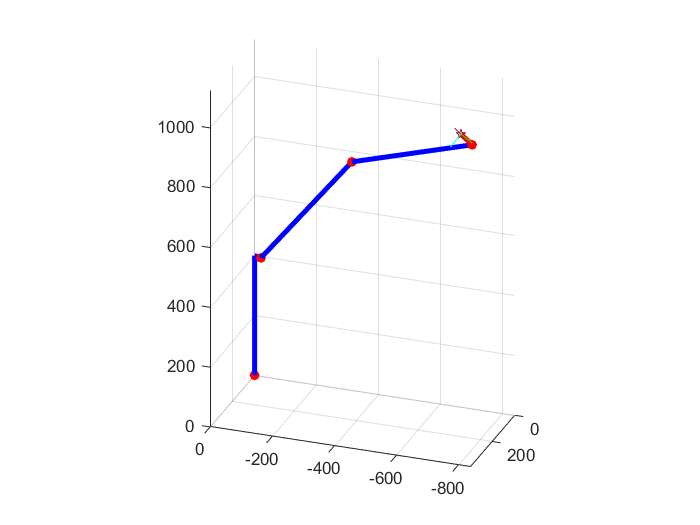

draw_robot(q_test,d)

% Substitute angles in symbolical form an'''d convert to double
double(subs(FK, [q1 q2 q3 q4 q5 q6], q_test))

ans = 	1.0e+03 *

    0.0001    0.0005   -0.0009   -0.7960
    0.0007    0.0006    0.0004    0.3587
    0.0007   -0.0007   -0.0003    1.0902
         0         0         0    0.0010



% disp('Test configuration')
% q_test = [pi/3 -pi/6 11 -1 -1 -1] % test configuration
% draw_robot(q_test,L)
% Substitute angles in symbolical form and convert to double
T=double(subs(FK, [q1 q2 q3 q4 q5 q6], q_test))

T = 	1.0e+03 *

    0.0001    0.0005   -0.0009   -0.7960
    0.0007    0.0006    0.0004    0.3587
    0.0007   -0.0007   -0.0003    1.0902
         0         0         0    0.0010


## 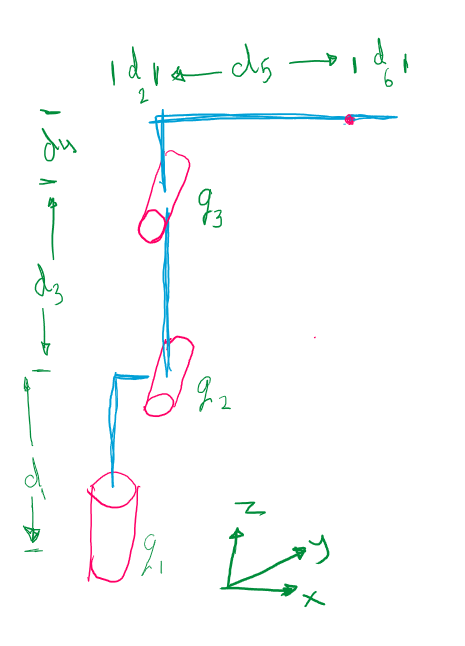

## Jacobian

### Numerical derivatives

Forward kinematics

syms q1 q2 q3 q4 q5 q6 real

H=simplify(Tz(d1)*Rz(q(1))*Tx(d2)*Ry(q(2))*Tz(d3)*Ry(q(3))*Tz(d4)*Tx(d5)*Rx(q(4))*Ry(q(5))*Rx(q(6))*Tx(d6))

where

## 
$$H=\left\lbrack \begin{array}{cc}
R & T\\
0 & 1
\end{array}\right\rbrack$$


R = simplify(H(1:3,1:3))

% forward kinematics
H =Tz(d1)*Rz(q(1))*Tx(d2)*Ry(q(2))*Tz(d3)*Ry(q(3))*Tz(d4)*Tx(d5)*Rx(q(4))*Ry(q(5))*Rx(q(6))*Tx(d6);
H=simplify(H);
% extract rotation matrix
R = simplify(H(1:3,1:3));
% diff by q1
Td=Tz(d1)*Rzd(q(1))*Tx(d2)*Ry(q(2))*Tz(d3)*Ry(q(3))*Tz(d4)*Tx(d5)*Rx(q(4))*Ry(q(5))*Rx(q(6))*Tx(d6)*...
    [R^-1 zeros(3,1);0 0 0 1];
% extract 6 components from 4x4 Td matrix to Jacobian 1st column
J1 = [Td(1,4), Td(2,4), Td(3,4), Td(3,2), Td(1,3), Td(2,1)]' ;
% diff by q2
Td=Tz(d1)*Rz(q(1))*Tx(d2)*Ryd(q(2))*Tz(d3)*Ry(q(3))*Tz(d4)*Tx(d5)*Rx(q(4))*Ry(q(5))*Rx(q(6))*Tx(d6)*...
    [R^-1 zeros(3,1);0 0 0 1];
% extract 6 components from 4x4 Td matrix to Jacobian 2nd column
J2 = [Td(1,4), Td(2,4), Td(3,4), Td(3,2), Td(1,3), Td(2,1)]' ;
% diff by q3
Td=Tz(d1)*Rz(q(1))*Tx(d2)*Ry(q(2))*Tz(d3)*Ryd(q(3))*Tz(d4)*Tx(d5)*Rx(q(4))*Ry(q(5))*Rx(q(6))*Tx(d6)*...
    [R^-1 zeros(3,1);0 0 0 1];
% extract 6 components from 4x4 Td matrix to Jacobian 3rd column
J3 = [Td(1,4), Td(2,4), Td(3,4), Td(3,2), Td(1,3), Td(2,1)]' ;
% diff by q4
Td=Tz(d1)*Rz(q(1))*Tx(d2)*Ry(q(2))*Tz(d3)*Ry(q(3))*Tz(d4)*Tx(d5)*Rxd(q(4))*Ry(q(5))*Rx(q(6))*Tx(d6)*...
    [R^-1 zeros(3,1);0 0 0 1];
% extract 6 components from 4x4 Td matrix to Jacobian 4th column
J4 = [Td(1,4), Td(2,4), Td(3,4), Td(3,2), Td(1,3), Td(2,1)]' ;
Td=Tz(d1)*Rz(q(1))*Tx(d2)*Ry(q(2))*Tz(d3)*Ry(q(3))*Tz(d4)*Tx(d5)*Rx(q(4))*Ryd(q(5))*Rx(q(6))*Tx(d6)*...
    [R^-1 zeros(3,1);0 0 0 1];
% extract 6 components from 4x4 Td matrix to Jacobian 5th column
J5 = [Td(1,4), Td(2,4), Td(3,4), Td(3,2), Td(1,3), Td(2,1)]' ;
Td=Tz(d1)*Rz(q(1))*Tx(d2)*Ry(q(2))*Tz(d3)*Ry(q(3))*Tz(d4)*Tx(d5)*Rx(q(4))*Ry(q(5))*Rxd(q(6))*Tx(d6)*...
    [R^-1 zeros(3,1);0 0 0 1];
% extract 6 components from 4x4 Td matrix to Jacobian 6th column
J6 = [Td(1,4), Td(2,4), Td(3,4), Td(3,2), Td(1,3), Td(2,1)]' ;
% Full Jacobian 6x6
Jq1 = [simplify(J1), simplify(J2), simplify(J3), simplify(J4), simplify(J5), simplify(J6)]

singularity=simplify(det(Jq1))

$$singularity = -14000\,\sin\left(q_{5}\right)\,\left(25\,\cos\left(q_{2}\right)+515\,\cos\left(q_{3}\right)-515\,\sin\left(q_{2}\right)+25\,\sin\left(q_{3}\right)+11536\,\cos\left(q_{3}\right)\,\sin\left(q_{2}\right)+560\,\sin\left(q_{2}\right)\,\sin\left(q_{3}\right)+10584\,\cos\left(q_{2}\right)\,{\cos\left(q_{3}\right)}^{2}+1030\,{\cos\left(q_{3}\right)}^{2}\,\sin\left(q_{2}\right)+1030\,\cos\left(q_{2}\right)\,\cos\left(q_{3}\right)\,\sin\left(q_{3}\right)-10584\,\cos\left(q_{3}\right)\,\sin\left(q_{2}\right)\,\sin\left(q_{3}\right)\right)$$